%Given Values
r_i = .003/2; %m
r_o = .005/2; %m
k = .3; %W/m^2
T_inf = 300; %K
T_max = 450; %K
h = 80; %W/m^2K
Resistance = .0328; %Ohms/m

%Part 1
R_cond = log(r_o/r_i)/(2*pi*k)

R_cond = 0.2710

R_conv = 1/(h*2*pi*r_o)

R_conv = 0.7958

R_total = R_conv + R_cond

R_total = 1.0668


I = sqrt((T_max-T_inf)/(R_total*Resistance))

I = 65.4745


%Part 2
r_o_2 = (.002:.0001:.005);
R_cond_2 = log(r_o_2./r_i)/(2*pi*k);
R_conv_2 = 1./(h*2*pi*r_o_2);
R_total_2 = R_conv_2 + R_cond_2;

q_r = (T_max-T_inf)./R_total_2;

%Finding the critical radius of insullation 
polys = polyfit(r_o_2(2:end),diff(q_r), 3);
fun = @(x) polys(1)*x^3 + polys(2)*x^2 +polys(3)*x +polys(4);
critical_radius = fzero(fun,.004)

critical_radius = 0.0038

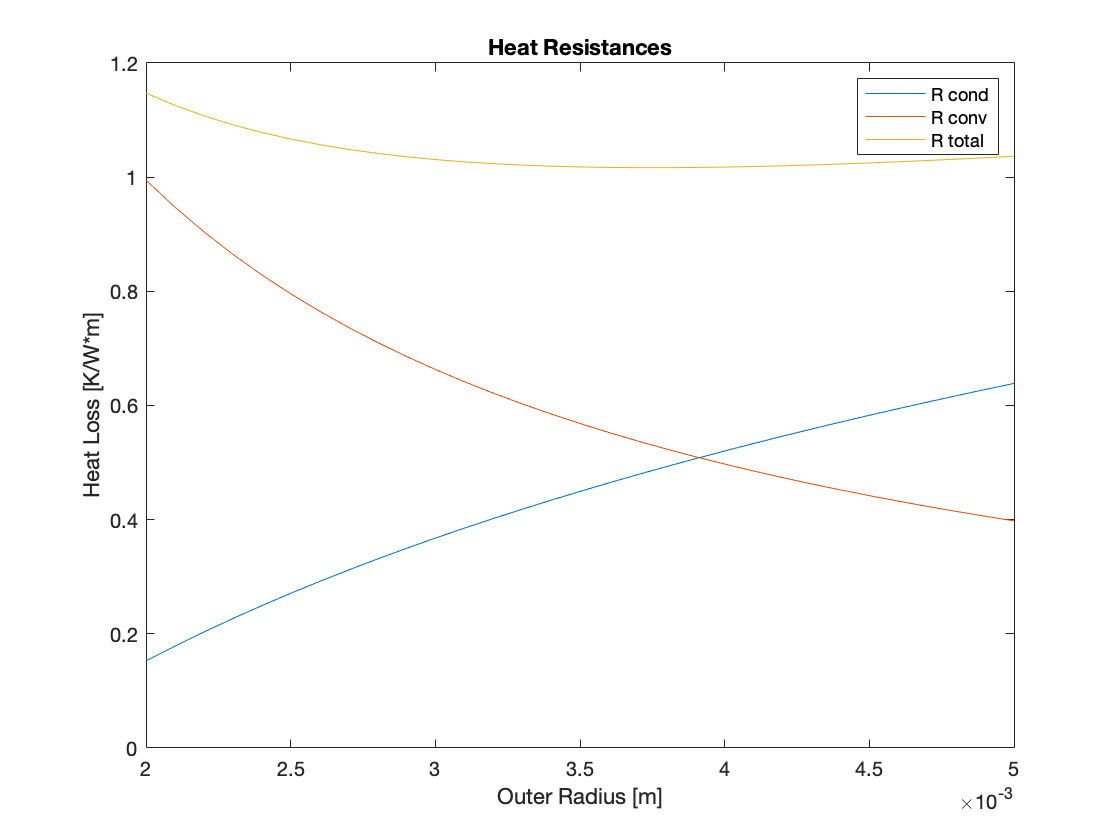

%At a outer radius of 3.8mm (outer diameter of 7.6mm) R_total_2 is at a
%minimum and q_r is at a maximum. This critical radius occurs because of
%the the relationship between heat conduction and heat convection as the
%radius and area of the wire increase. 

clf
plot(r_o_2,R_cond_2, r_o_2, R_conv_2,r_o_2, R_total_2)
xlabel("Outer Radius [m]")
ylabel("Heat Loss [K/W*m]")
title('Heat Resistances')
legend('R cond', 'R conv', 'R total')

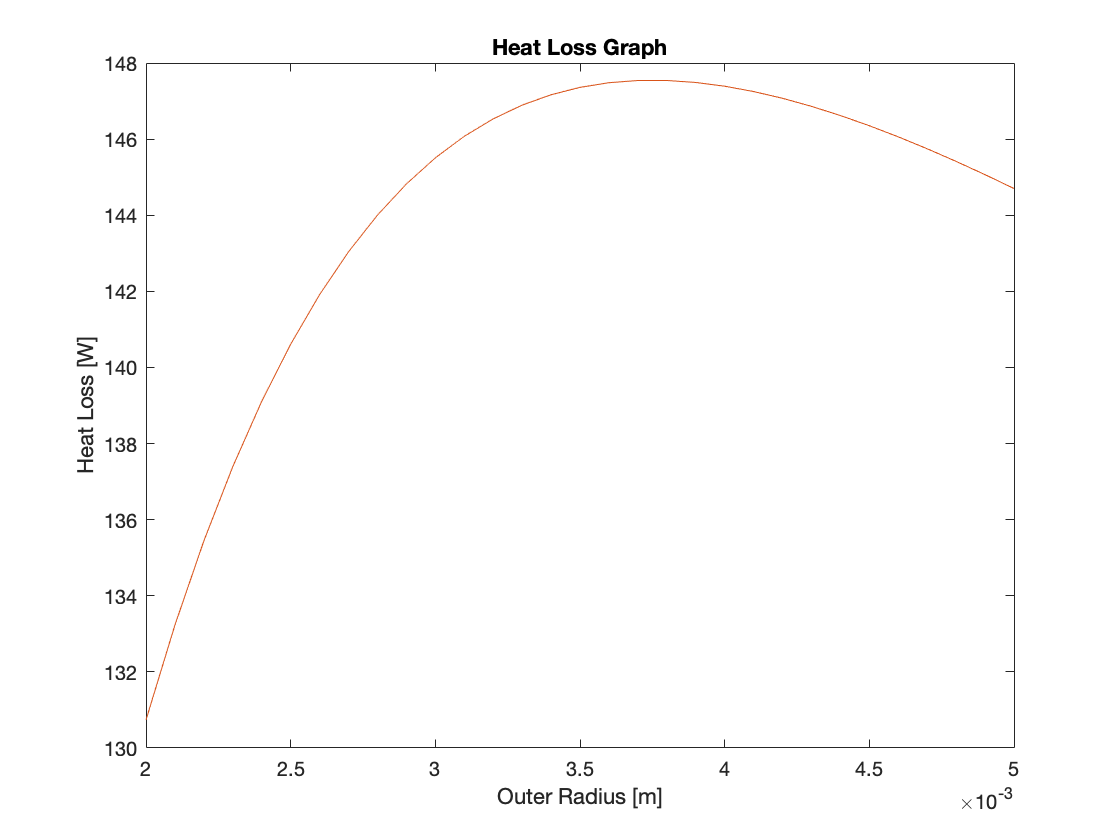


I2 = sqrt((T_max-T_inf)./(R_total_2.*Resistance));
q_r_2 = I2.^2.*Resistance;

plot(r_o_2, q_r, r_o_2, q_r_2)
xlabel("Outer Radius [m]")
ylabel("Heat Loss [W]")
title('Heat Loss Graph')


%Note that q_r (found using resistance method) and q_r_2 (found using P =
%I^2*r) are exactly equal and are ploted over each other on the Heat Loss
%Graph
